**LEP 5-8 : Reversible gas phase reaction in a packed bed with Pressure drop**

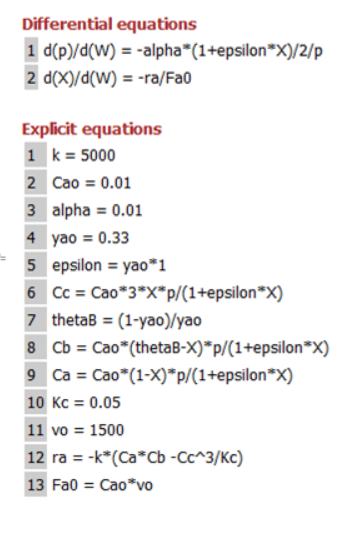

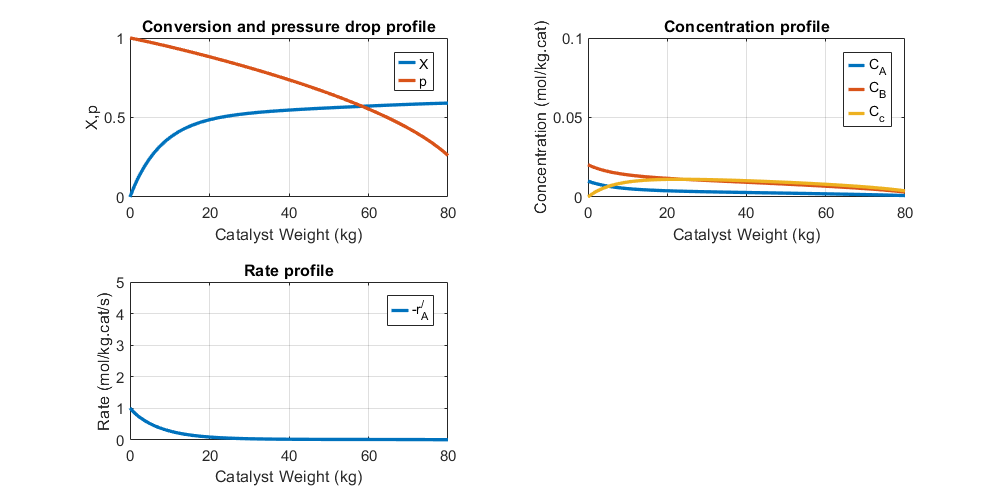

Vspan = [0 80]; 
y0 = [0,1]; 
k = 5000; 
Cao =0.01;
alpha =0.01; 
yao = 0.33;
Kc = 0.05; 
vo=1500;
[v,y]=ode45(@(v,y)ODEfun(v,y,k,Cao,alpha,yao,Kc,vo),Vspan,y0);
tiledlayout(2,2)
set (gcf,'Position',[0,0.1,800,400])
nexttile
plot(v,y(:,1),v,y(:,2),'LineWidth',2)
xlabel('Catalyst Weight (kg)')
ylabel('X,p')
leg=legend('X','p');
leg.ItemTokenSize=[10,10];
axis([0 80 0 1])
title('Conversion and pressure drop profile')
grid on

nexttile
epsilon = yao*1;
thetaB = (1-yao)/yao ;
z=size(y);
for i=1 : z(1,1)
    % Calculating the values of concentration from its expression 
  Ca(i) = Cao*(1-y(i,1))*y(i,2)/(1+epsilon*y(i,1));
Cb(i) = Cao*(thetaB-y(i,1))*y(i,2)/(1+epsilon*y(i,1));
Cc(i) = Cao*3*y(i,1)*y(i,2)/(1+epsilon*y(i,1));
ra(i) = -k*(Ca(i)*Cb(i) -Cc(i)^3/Kc);
end
plot(v,Ca(1:z(1,1)),v,Cb(1:z(1,1)),v,Cc(1:z(1,1)),'LineWidth',2)
xlabel('Catalyst Weight (kg)')
ylabel('Concentration (mol/kg.cat)')
leg=legend('C_A','C_B','C_c');
leg.ItemTokenSize=[10,10];
title('Concentration profile')
axis([0 80 0 0.1])
grid on
nexttile
plot(v,-ra(1:z(1,1)),'LineWidth',2)
xlabel('Catalyst Weight (kg)')
ylabel('Rate (mol/kg.cat/s)')
axis([0 80 0 5])
leg=legend('-r_A^/');
title('Rate profile')
leg.ItemTokenSize=[10,10];
grid on

function dYfuncvecdW = ODEfun(V,Yfuncvec,k,Cao,alpha,yao,Kc,vo); 
X = Yfuncvec(1); 
p= Yfuncvec(2); 
% Explicit equations
epsilon = yao*1; 
thetaB = (1-yao)/yao ;
Fa0 = Cao*vo;
Ca = Cao*(1-X)*p/(1+epsilon*X);
Cb = Cao*(thetaB-X)*p/(1+epsilon*X);
Cc = Cao*3*X*p/(1+epsilon*X);
ra = -k*(Ca*Cb -Cc^3/Kc);
% Differential equations
dXdW = -ra/Fa0; 
dpdW = -alpha*(1+epsilon*X)/2/p; 
dYfuncvecdW =[dXdW; dpdW]; 
end